## Gabriel Werpel Fernandes

## May 2024

## Load Data

% Close all figures and clear variables
clc;
close all;
clearvars;

%Process EEG Data
data = processAllEEGData();

Data for file A1_Full_Block.bdf processed successfully
Data for file A3_Full_Block.bdf processed successfully
Data for file A4_Full_Block.bdf processed successfully
Data for file A6_Alpha.bdf processed successfully
Data for file A7_Alpha.bdf processed successfully
Data for file A8_Alpha.bdf processed successfully
Data for file A9_Alpha.bdf processed successfully
Data for file C11_Alpha.bdf processed successfully
Data for file C12_Alpha.bdf processed successfully
Data for file C13_Alpha.bdf processed successfully
Data for file C14_Alpha.bdf processed successfully
Data for file C15_Alpha.bdf processed successfully
Data for file C1_Alpha.bdf processed successfully


## Plot Time-Series

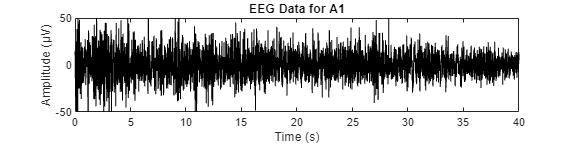

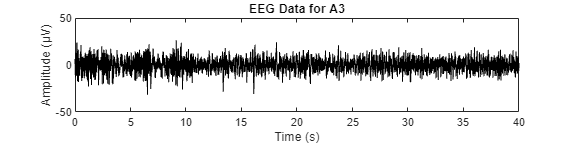

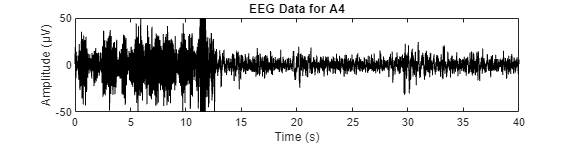

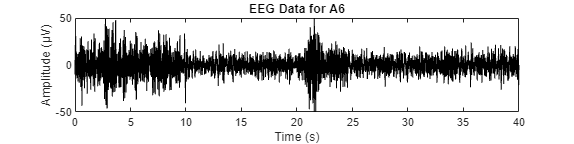

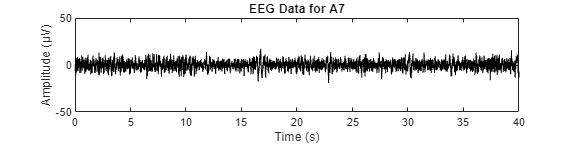

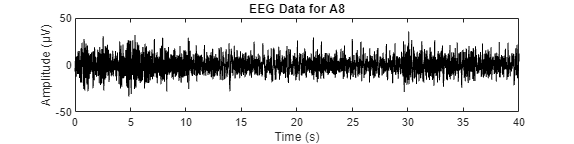

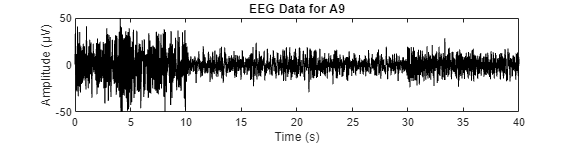

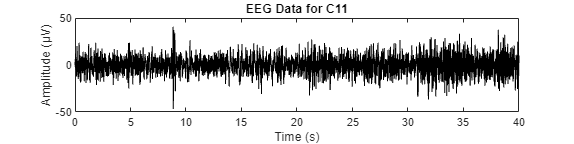

% Plot all EEG data
plotAllEEGData(data);

## Segment Data

% Segment the EEG data
segmentedData = segmentEEGDataNew(data);

## Compute and Plot Fourier Spectrum

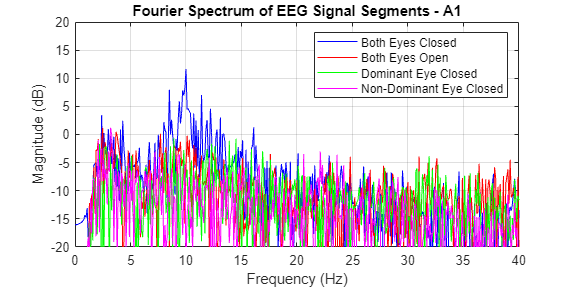

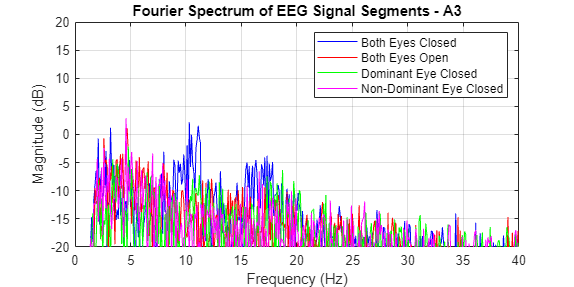

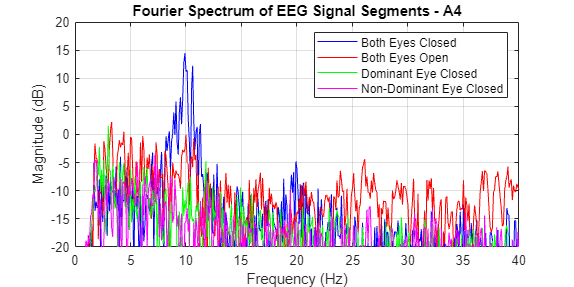

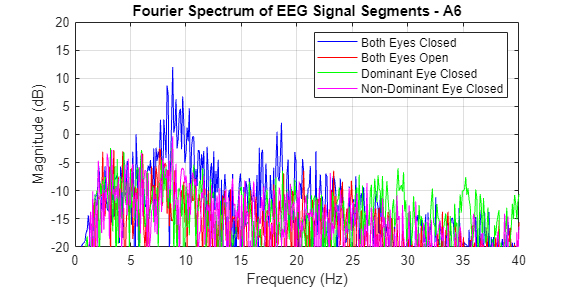

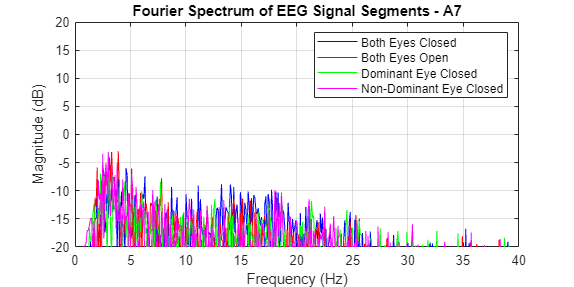

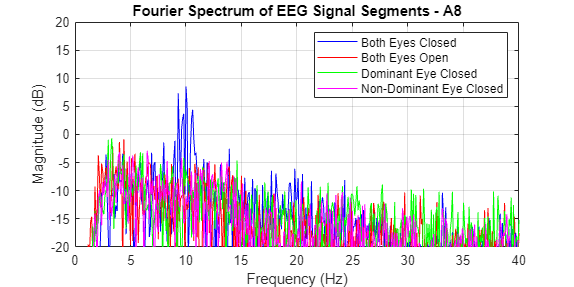

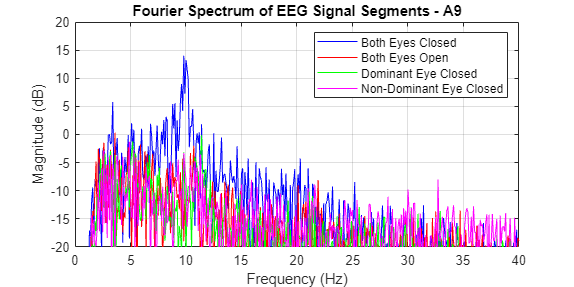

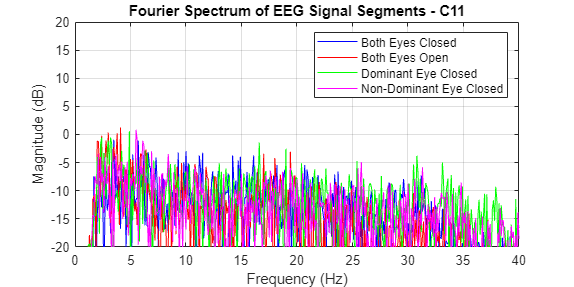

% Compute and plot the Fourier spectra, and get the spectra results
spectraResults = plotAndComputeFourierSpectra(segmentedData);

## Power, Frequency and Reactivity

% Compute the reactivity and other metrics
reactivityResults = computeReactivity(spectraResults);

Key: A1
Maximum Power in BE_Closed (8-12 Hz): 11.623784 dB at 10.000488 Hz
Power in BE_Open at 10.000488 Hz: -5.624601 dB
Power in LE_Closed at 10.000488 Hz: -7.628942 dB
Power in RE_Closed at 10.000488 Hz: -23.819438 dB
Reactivity (Closed - Open): 17.248386 dB
Maximum Power in BE_Open (8-12 Hz): -0.246443 dB at 10.100493 Hz
Difference between max BE_Closed and max BE_Open: 11.870227 dB

Key: A3
Maximum Power in BE_Closed (8-12 Hz): 2.192635 dB at 10.300503 Hz
Power in BE_Open at 10.300503 Hz: -11.555578 dB
Power in LE_Closed at 10.300503 Hz: -15.133462 dB
Power in RE_Closed at 10.300503 Hz: -20.633957 dB
Reactivity (Closed - Open): 13.748213 dB
Maximum Power in BE_Open (8-12 Hz): -5.164243 dB at 8.000391 Hz
Difference between max BE_Closed and max BE_Open: 7.356878 dB

Key: A4
Maximum Power in BE_Closed (8-12 Hz): 14.459347 dB at 9.900483 Hz
Power in BE_Open at 9.900483 Hz: -2.650362 dB
Power in LE_Closed at 9.900483 Hz: -11.704272 dB
Power in RE_Closed at 9.900483 Hz: -15.597795 dB
R

## Bandwidth

% Define the dB drop for bandwidth calculation
dB_drop = 3;

% Compute the bandwidth for all segmented data
bandwidthResults = computeBandwidth(spectraResults, dB_drop);

Key: A1
Bandwidth for BE_Closed around 10.000488 Hz: 0.200010 Hz (9.900483 Hz to 10.100493 Hz)

Key: A3
Bandwidth for BE_Closed around 10.300503 Hz: 0.200010 Hz (10.200498 Hz to 10.400508 Hz)

Key: A4
Bandwidth for BE_Closed around 9.900483 Hz: 0.300015 Hz (9.700474 Hz to 10.000488 Hz)

Key: A6
Bandwidth for BE_Closed around 8.800430 Hz: 0.200010 Hz (8.700425 Hz to 8.900435 Hz)

Key: A7
Bandwidth for BE_Closed around 11.100542 Hz: 0.200010 Hz (11.000537 Hz to 11.200547 Hz)

Key: A8
Bandwidth for BE_Closed around 10.000488 Hz: 0.200010 Hz (9.900483 Hz to 10.100493 Hz)

Key: A9
Bandwidth for BE_Closed around 9.800479 Hz: 0.200010 Hz (9.700474 Hz to 9.900483 Hz)

Key: C1
Bandwidth for BE_Closed around 11.300552 Hz: 0.200010 Hz (11.200547 Hz to 11.400557 Hz)

Key: C2
Bandwidth for BE_Closed around 10.200498 Hz: 0.200010 Hz (10.100493 Hz to 10.300503 Hz)

Key: C3
Bandwidth for BE_Closed around 10.800527 Hz: 0.300015 Hz (10.600518 Hz to 10.900532 Hz)



## Coherence

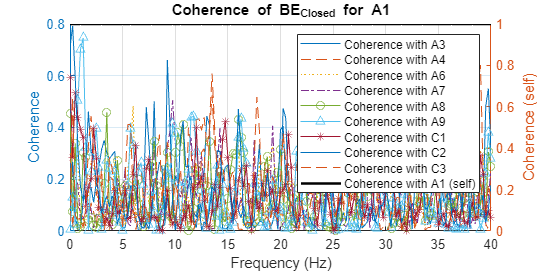

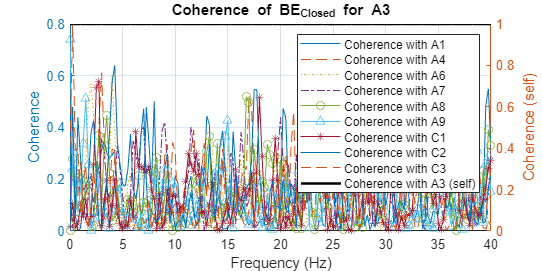

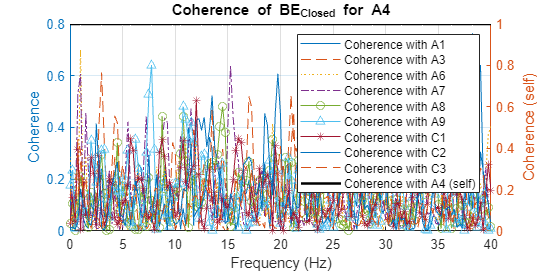

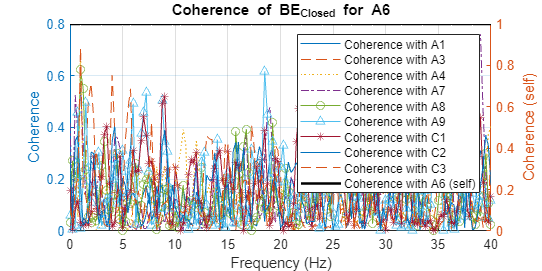

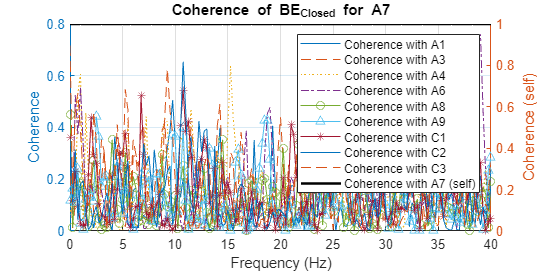

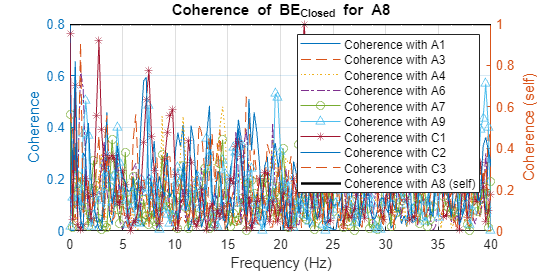

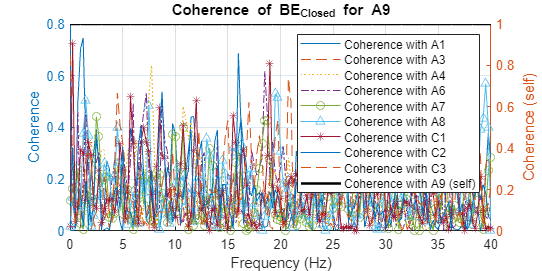

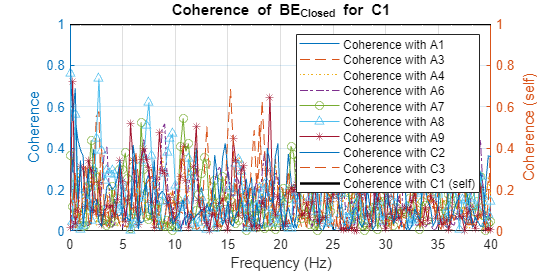

% Define parameters for mscohere
% window = 256;     % Window size for coherence calculation
% noverlap = 128;   % Number of overlapping samples
% nfft = 512;       % Number of FFT points

window = []; %2048;     % Window size for coherence calculation
noverlap = []; % 2048/2;   % Number of overlapping samples
nfft = [];       % Number of FFT points

% Calculate and plot coherence for BE_Closed segments
coherenceResults = calculateAndPlotCoherence(segmentedData, window, noverlap, nfft);

## Skewness and Kurtosis

% Calculate the skewness and kurtosis for the alpha band of the Fourier distributions
alphaStatsResults = calculateAlphaStats(spectraResults);

Key: A1
Skewness and Kurtosis for BE_Closed alpha band:
Skewness: -0.305733, Kurtosis: 2.860446
Skewness and Kurtosis for BE_Open alpha band:
Skewness: -0.926800, Kurtosis: 3.535473
Skewness and Kurtosis for LE_Closed alpha band:
Skewness: -1.031501, Kurtosis: 3.900639
Skewness and Kurtosis for RE_Closed alpha band:
Skewness: -1.019793, Kurtosis: 4.196412

Key: A3
Skewness and Kurtosis for BE_Closed alpha band:
Skewness: -0.079550, Kurtosis: 2.097852
Skewness and Kurtosis for BE_Open alpha band:
Skewness: -0.324769, Kurtosis: 2.373856
Skewness and Kurtosis for LE_Closed alpha band:
Skewness: -0.636723, Kurtosis: 2.860640
Skewness and Kurtosis for RE_Closed alpha band:
Skewness: -2.182997, Kurtosis: 9.319870

Key: A4
Skewness and Kurtosis for BE_Closed alpha band:
Skewness: -0.448642, Kurtosis: 3.812519
Skewness and Kurtosis for BE_Open alpha band:
Skewness: -1.262329, Kurtosis: 4.093361
Skewness and Kurtosis for LE_Closed alpha band:
Skewness: -0.747361, Kurtosis: 3.655371
Skewness and

## PSD - (Power Spectral Density) Welch's Method

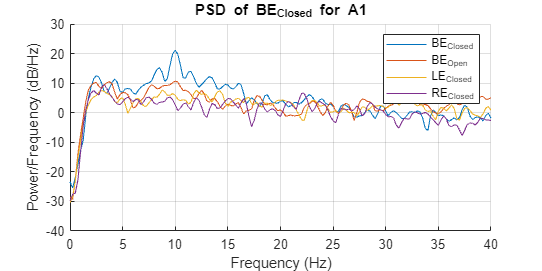

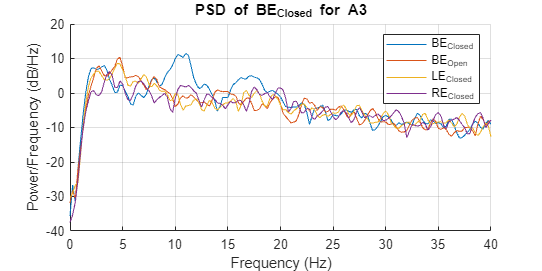

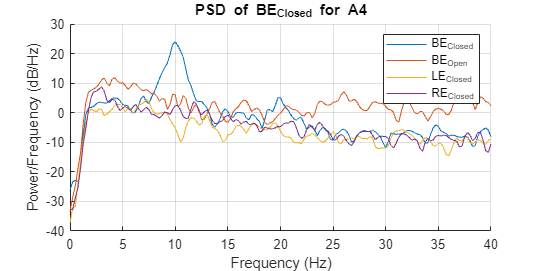

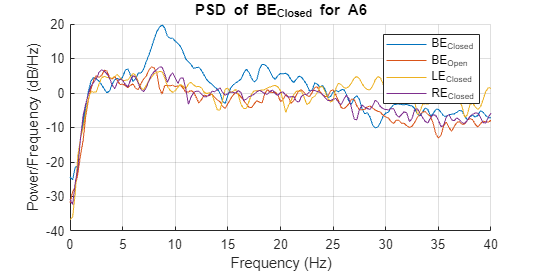

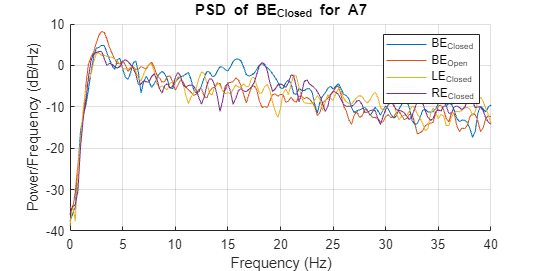

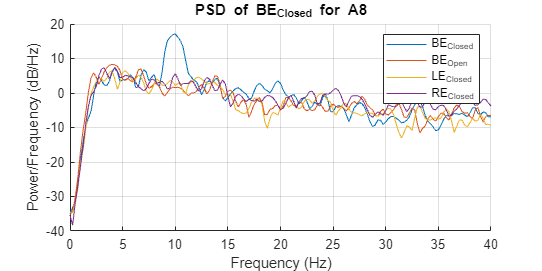

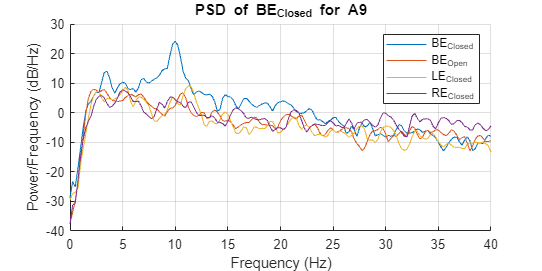

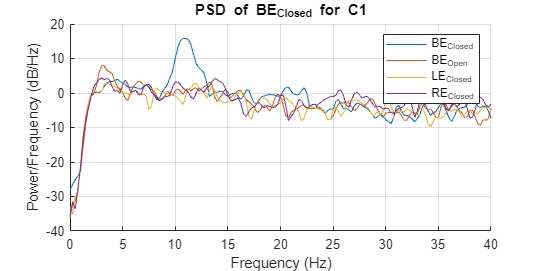

% Define parameters for pwelch
window = [];%2048;     % Window size for PSD calculation
noverlap = [];%2028/2;   % Number of overlapping samples
nfft = [];       % Number of FFT points

% Compute and plot PSD for BE_Closed segments
psdResults = computeAndPlotPSD(segmentedData, window, noverlap, nfft);

## PSD - Skewness and Kurtosis

% Calculate the skewness and kurtosis for the alpha band of the PSD distributions
alphaStatsResultsPSD = calculateAlphaStatsFromPSD(psdResults);

Key: A1
Skewness and Kurtosis for BE_Closed alpha band:
Skewness: 0.752001, Kurtosis: 2.577815
Skewness and Kurtosis for BE_Open alpha band:
Skewness: -0.685500, Kurtosis: 2.628822
Skewness and Kurtosis for LE_Closed alpha band:
Skewness: -0.147487, Kurtosis: 2.099172
Skewness and Kurtosis for RE_Closed alpha band:
Skewness: -0.238901, Kurtosis: 2.310308

Key: A3
Skewness and Kurtosis for BE_Closed alpha band:
Skewness: 0.008235, Kurtosis: 1.472170
Skewness and Kurtosis for BE_Open alpha band:
Skewness: 0.683608, Kurtosis: 3.047353
Skewness and Kurtosis for LE_Closed alpha band:
Skewness: 0.154463, Kurtosis: 2.107753
Skewness and Kurtosis for RE_Closed alpha band:
Skewness: -0.709695, Kurtosis: 2.697237

Key: A4
Skewness and Kurtosis for BE_Closed alpha band:
Skewness: -0.027958, Kurtosis: 1.785881
Skewness and Kurtosis for BE_Open alpha band:
Skewness: -0.221920, Kurtosis: 1.872222
Skewness and Kurtosis for LE_Closed alpha band:
Skewness: -0.878606, Kurtosis: 2.621517
Skewness and Kur

## PSD - Power, Frequency and Reactivity

% Compute the reactivity and other metrics from PSD
psdReactivityResults = computePSDReactivity(psdResults, dB_drop);

Key: A1
Maximum Power in BE_Closed (8-12 Hz): 21.159499 dB/Hz at 10.000000 Hz
Power in BE_Open at 10.000000 Hz: 10.673014 dB/Hz
Power in LE_Closed at 10.000000 Hz: 5.974838 dB/Hz
Power in RE_Closed at 10.000000 Hz: 2.612862 dB/Hz
Reactivity (Closed - Open): 10.486485 dB/Hz
Maximum Power in BE_Open (8-12 Hz): 10.673014 dB/Hz at 10.000000 Hz
Difference between max BE_Closed and max BE_Open: 10.486485 dB/Hz

Key: A3
Maximum Power in BE_Closed (8-12 Hz): 11.485780 dB/Hz at 11.000000 Hz
Power in BE_Open at 11.000000 Hz: -1.535814 dB/Hz
Power in LE_Closed at 11.000000 Hz: -3.770258 dB/Hz
Power in RE_Closed at 11.000000 Hz: 1.732292 dB/Hz
Reactivity (Closed - Open): 13.021593 dB/Hz
Maximum Power in BE_Open (8-12 Hz): 4.796742 dB/Hz at 8.000000 Hz
Difference between max BE_Closed and max BE_Open: 6.689038 dB/Hz

Key: A4
Maximum Power in BE_Closed (8-12 Hz): 23.986240 dB/Hz at 10.000000 Hz
Power in BE_Open at 10.000000 Hz: 6.035628 dB/Hz
Power in LE_Closed at 10.000000 Hz: -5.181699 dB/Hz
Power

## PSD - Bandwidth

% Compute the bandwidth for all segmented data from PSD
psdBandwidthResults = computePSDBandwidth(psdResults, dB_drop);

Key: A1
Bandwidth for BE_Closed around 10.000000 Hz: 1.000000 Hz (9.500000 Hz to 10.500000 Hz)

Key: A3
Bandwidth for BE_Closed around 11.000000 Hz: 1.750000 Hz (9.750000 Hz to 11.500000 Hz)

Key: A4
Bandwidth for BE_Closed around 10.000000 Hz: 1.000000 Hz (9.500000 Hz to 10.500000 Hz)

Key: A6
Bandwidth for BE_Closed around 8.750000 Hz: 1.250000 Hz (8.000000 Hz to 9.250000 Hz)

Key: A7
Bandwidth for BE_Closed around 8.750000 Hz: 1.750000 Hz (7.750000 Hz to 9.500000 Hz)

Key: A8
Bandwidth for BE_Closed around 10.000000 Hz: 1.750000 Hz (9.000000 Hz to 10.750000 Hz)

Key: A9
Bandwidth for BE_Closed around 10.000000 Hz: 1.000000 Hz (9.500000 Hz to 10.500000 Hz)

Key: C1
Bandwidth for BE_Closed around 10.750000 Hz: 1.750000 Hz (10.000000 Hz to 11.750000 Hz)

Key: C2
Bandwidth for BE_Closed around 10.250000 Hz: 1.000000 Hz (9.750000 Hz to 10.750000 Hz)

Key: C3
Bandwidth for BE_Closed around 10.750000 Hz: 1.000000 Hz (10.250000 Hz to 11.250000 Hz)



## Data Analysis

Hypothesis Test Results:
             Metric             p_value       Significance    
    ________________________    _______    ___________________

    {'Reactivity'          }    0.93536    {'Not Significant'}
    {'Max Closed-Open Diff'}    0.73765    {'Not Significant'}
    {'Bandwidth Closed'    }    0.70272    {'Not Significant'}
    {'Skewness BE Closed'  }    0.89709    {'Not Significant'}
    {'Kurtosis BE Closed'  }    0.37961    {'Not Significant'}
    {'Skewness BE Open'    }     0.8945    {'Not Significant'}
    {'Kurtosis BE Open'    }    0.24552    {'Not Significant'}
    {'Skewness LE Closed'  }    0.92305    {'Not Significant'}
    {'Kurtosis LE Closed'  }     0.8377    {'Not Significant'}
    {'Skewness RE Closed'  }    0.34294    {'Not Significant'}
    {'Kurtosis RE Closed'  }     0.2997    {'Not Significant'}
    {'Coherence'           }          1    {'Not Sign

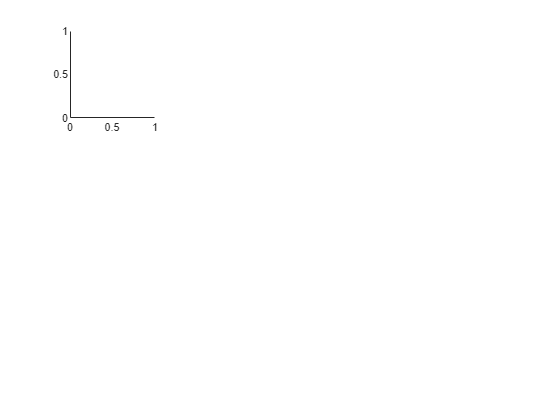

Error using horzcat
Dimensions of arrays being concatenated are not consistent.

Error in Data Analysis_Luke_v2.0>performHypothesisTests (line 159)
    boxplot([reactivity_A, reactivity_C], 'Labels', {'A*', 'C*'});

% Assuming 'psdReactivityResults', 'alphaStatsResults', 'psdBandwidthResults', and 'psdCoherenceResults'
% are the structures returned by the respective functions
%psdReactivityResults = computePSDReactivity(psdResults, dB_drop);
%alphaStatsResults = calculateAlphaStatsFromPSD(psdResults);
%psdBandwidthResults = computePSDBandwidth(psdResults, dB_drop);
%CoherenceResults = calculateAndPlotCoherence(segmentedData, window, noverlap, nfft);

% Perform hypothesis tests comparing A* and C* data
hypothesisTestResults = performHypothesisTests(psdReactivityResults, alphaStatsResults, psdBandwidthResults, CoherenceResults);

% Assuming 'psdReactivityResults', 'alphaStatsResults', 'psdBandwidthResults', and 'psdCoherenceResults'
% are the structures returned by the respective functions
psdReactivityResults


function hypothesisTestResults = performHypothesisTests(psdReactivityResults, alphaStatsResults, psdBandwidthResults, psdCoherenceResults)
    % Initialize the hypothesis test results structure
    hypothesisTestResults = struct;

    % Separate keys into A* and C* groups
    A_keys = {};
    C_keys = {};
    fields = fieldnames(psdReactivityResults);
    for i = 1:numel(fields)
        key = fields{i};
        if startsWith(key, 'A')
            A_keys{end+1} = key;
        elseif startsWith(key, 'C')
            C_keys{end+1} = key;
        end
    end

    % Ensure we have both A* and C* keys
    if isempty(A_keys) || isempty(C_keys)
        error('Both A* and C* groups must have data.');
    end

    % Helper function to extract values and perform t-tests
    function [p, A_values, C_values] = ttest2groups(dataStruct, fieldName)
        A_values = [];
        C_values = [];
        for k = 1:numel(A_keys)
            if isfield(dataStruct.(A_keys{k}), fieldName)
                A_values = [A_values; dataStruct.(A_keys{k}).(fieldName)];
            end
        end
        for k = 1:numel(C_keys)
            if isfield(dataStruct.(C_keys{k}), fieldName)
                C_values = [C_values; dataStruct.(C_keys{k}).(fieldName)];
            end
        end
        [~, p] = ttest2(A_values, C_values);
    end

    % Reactivity and max closed-open diff tests
    [hypothesisTestResults.reactivity, reactivity_A, reactivity_C] = ttest2groups(psdReactivityResults, 'reactivity');
    [hypothesisTestResults.max_closed_open_diff, max_diff_A, max_diff_C] = ttest2groups(psdReactivityResults, 'max_closed_open_diff');

    % Bandwidth tests
    [hypothesisTestResults.bandwidth_closed, bandwidth_A, bandwidth_C] = ttest2groups(psdBandwidthResults, 'bandwidth_closed');

    % Alpha band skewness and kurtosis tests
    [hypothesisTestResults.skewness_BE_Closed, skewness_BE_Closed_A, skewness_BE_Closed_C] = ttest2groups(alphaStatsResults, 'skewness_BE_Closed');
    [hypothesisTestResults.kurtosis_BE_Closed, kurtosis_BE_Closed_A, kurtosis_BE_Closed_C] = ttest2groups(alphaStatsResults, 'kurtosis_BE_Closed');
    [hypothesisTestResults.skewness_BE_Open, skewness_BE_Open_A, skewness_BE_Open_C] = ttest2groups(alphaStatsResults, 'skewness_BE_Open');
    [hypothesisTestResults.kurtosis_BE_Open, kurtosis_BE_Open_A, kurtosis_BE_Open_C] = ttest2groups(alphaStatsResults, 'kurtosis_BE_Open');
    [hypothesisTestResults.skewness_LE_Closed, skewness_LE_Closed_A, skewness_LE_Closed_C] = ttest2groups(alphaStatsResults, 'skewness_LE_Closed');
    [hypothesisTestResults.kurtosis_LE_Closed, kurtosis_LE_Closed_A, kurtosis_LE_Closed_C] = ttest2groups(alphaStatsResults, 'kurtosis_LE_Closed');
    [hypothesisTestResults.skewness_RE_Closed, skewness_RE_Closed_A, skewness_RE_Closed_C] = ttest2groups(alphaStatsResults, 'skewness_RE_Closed');
    [hypothesisTestResults.kurtosis_RE_Closed, kurtosis_RE_Closed_A, kurtosis_RE_Closed_C] = ttest2groups(alphaStatsResults, 'kurtosis_RE_Closed');

    % Coherence tests
    function [p, A_values, C_values] = ttest2coherence(dataStruct, A_keys, C_keys)
        A_values = [];
        C_values = [];
        for i = 1:numel(A_keys)
            for j = 1:numel(C_keys)
                if isfield(dataStruct.(A_keys{i}), C_keys{j})
                    A_values = [A_values; dataStruct.(A_keys{i}).(C_keys{j}).coherence];
                end
                if isfield(dataStruct.(C_keys{j}), A_keys{i})
                    C_values = [C_values; dataStruct.(C_keys{j}).(A_keys{i}).coherence];
                end
            end
        end
        [~, p] = ttest2(A_values, C_values);
    end

    [hypothesisTestResults.coherence, coherence_A, coherence_C] = ttest2coherence(psdCoherenceResults, A_keys, C_keys);

    % Create a table of results
    metrics = {'Reactivity', 'Max Closed-Open Diff', 'Bandwidth Closed', ...
               'Skewness BE Closed', 'Kurtosis BE Closed', 'Skewness BE Open', 'Kurtosis BE Open', ...
               'Skewness LE Closed', 'Kurtosis LE Closed', 'Skewness RE Closed', 'Kurtosis RE Closed', ...
               'Coherence'};
    p_values = [hypothesisTestResults.reactivity, hypothesisTestResults.max_closed_open_diff, ...
                hypothesisTestResults.bandwidth_closed, hypothesisTestResults.skewness_BE_Closed, ...
                hypothesisTestResults.kurtosis_BE_Closed, hypothesisTestResults.skewness_BE_Open, ...
                hypothesisTestResults.kurtosis_BE_Open, hypothesisTestResults.skewness_LE_Closed, ...
                hypothesisTestResults.kurtosis_LE_Closed, hypothesisTestResults.skewness_RE_Closed, ...
                hypothesisTestResults.kurtosis_RE_Closed, hypothesisTestResults.coherence];

    significance = arrayfun(@(p) ifelse(p < 0.05, 'Significant', 'Not Significant'), p_values, 'UniformOutput', false);

    results_table = table(metrics', p_values', significance', 'VariableNames', {'Metric', 'p_value', 'Significance'});

    % Display the results table
    disp('Hypothesis Test Results:');
    disp(results_table);

    % Plot the comparisons
    figure;
    subplot(3, 4, 1);
    boxplot([reactivity_A, reactivity_C], 'Labels', {'A*', 'C*'});
    title('Reactivity');

    subplot(3, 4, 2);
    boxplot([max_diff_A, max_diff_C], 'Labels', {'A*', 'C*'});
    title('Max Closed-Open Diff');

    subplot(3, 4, 3);
    boxplot([bandwidth_A, bandwidth_C], 'Labels', {'A*', 'C*'});
    title('Bandwidth Closed');

    subplot(3, 4, 4);
    boxplot([skewness_BE_Closed_A, skewness_BE_Closed_C], 'Labels', {'A*', 'C*'});
    title('Skewness BE Closed');

    subplot(3, 4, 5);
    boxplot([kurtosis_BE_Closed_A, kurtosis_BE_Closed_C], 'Labels', {'A*', 'C*'});
    title('Kurtosis BE Closed');

    subplot(3, 4, 6);
    boxplot([skewness_BE_Open_A, skewness_BE_Open_C], 'Labels', {'A*', 'C*'});
    title('Skewness BE Open');

    subplot(3, 4, 7);
    boxplot([kurtosis_BE_Open_A, kurtosis_BE_Open_C], 'Labels', {'A*', 'C*'});
    title('Kurtosis BE Open');

    subplot(3, 4, 8);
    boxplot([skewness_LE_Closed_A, skewness_LE_Closed_C], 'Labels', {'A*', 'C*'});
    title('Skewness LE Closed');

    subplot(3, 4, 9);
    boxplot([kurtosis_LE_Closed_A, kurtosis_LE_Closed_C], 'Labels', {'A*', 'C*'});
    title('Kurtosis LE Closed');

    subplot(3, 4, 10);
    boxplot([skewness_RE_Closed_A, skewness_RE_Closed_C], 'Labels', {'A*', 'C*'});
    title('Skewness RE Closed');

    subplot(3, 4, 11);
    boxplot([kurtosis_RE_Closed_A, kurtosis_RE_Closed_C], 'Labels', {'A*', 'C*'});
    title('Kurtosis RE Closed');

    subplot(3, 4, 12);
    boxplot([coherence_A, coherence_C], 'Labels', {'A*', 'C*'});
    title('Coherence');
end

% Helper function for conditional string selection
function result = ifelse(condition, trueResult, falseResult)
    if condition
        result = trueResult;
    else
        result = falseResult;
    end
end


function hypothesisTestResults = performHypothesisTests2(psdReactivityResults, alphaStatsResults, psdBandwidthResults, psdCoherenceResults)
    % Initialize the hypothesis test results structure
    hypothesisTestResults = struct;

    % Separate keys into A* and C* groups
    A_keys = {};
    C_keys = {};
    fields = fieldnames(psdReactivityResults);
    for i = 1:numel(fields)
        key = fields{i};
        if startsWith(key, 'A')
            A_keys{end+1} = key;
        elseif startsWith(key, 'C')
            C_keys{end+1} = key;
        end
    end

    % Ensure we have both A* and C* keys
    if isempty(A_keys) || isempty(C_keys)
        error('Both A* and C* groups must have data.');
    end

    % Helper function to extract values and perform t-tests
    function p = ttest2groups(dataStruct, fieldName)
        A_values = [];
        C_values = [];
        for k = 1:numel(A_keys)
            if isfield(dataStruct.(A_keys{k}), fieldName)
                A_values = [A_values; dataStruct.(A_keys{k}).(fieldName)];
            end
        end
        for k = 1:numel(C_keys)
            if isfield(dataStruct.(C_keys{k}), fieldName)
                C_values = [C_values; dataStruct.(C_keys{k}).(fieldName)];
            end
        end
        [~, p] = ttest2(A_values, C_values);
    end

    % Reactivity and max closed-open diff tests
    hypothesisTestResults.reactivity = ttest2groups(psdReactivityResults, 'reactivity');
    hypothesisTestResults.max_closed_open_diff = ttest2groups(psdReactivityResults, 'max_closed_open_diff');

    % Bandwidth tests
    hypothesisTestResults.bandwidth_closed = ttest2groups(psdBandwidthResults, 'bandwidth_closed');

    % Alpha band skewness and kurtosis tests
    hypothesisTestResults.skewness_BE_Closed = ttest2groups(alphaStatsResults, 'skewness_BE_Closed');
    hypothesisTestResults.kurtosis_BE_Closed = ttest2groups(alphaStatsResults, 'kurtosis_BE_Closed');
    hypothesisTestResults.skewness_BE_Open = ttest2groups(alphaStatsResults, 'skewness_BE_Open');
    hypothesisTestResults.kurtosis_BE_Open = ttest2groups(alphaStatsResults, 'kurtosis_BE_Open');
    hypothesisTestResults.skewness_LE_Closed = ttest2groups(alphaStatsResults, 'skewness_LE_Closed');
    hypothesisTestResults.kurtosis_LE_Closed = ttest2groups(alphaStatsResults, 'kurtosis_LE_Closed');
    hypothesisTestResults.skewness_RE_Closed = ttest2groups(alphaStatsResults, 'skewness_RE_Closed');
    hypothesisTestResults.kurtosis_RE_Closed = ttest2groups(alphaStatsResults, 'kurtosis_RE_Closed');

    % Coherence tests
    function p = ttest2coherence(dataStruct, A_keys, C_keys)
        A_values = [];
        C_values = [];
        for i = 1:numel(A_keys)
            for j = 1:numel(C_keys)
                if isfield(dataStruct.(A_keys{i}), C_keys{j})
                    A_values = [A_values; dataStruct.(A_keys{i}).(C_keys{j}).coherence];
                end
                if isfield(dataStruct.(C_keys{j}), A_keys{i})
                    C_values = [C_values; dataStruct.(C_keys{j}).(A_keys{i}).coherence];
                end
            end
        end
        [~, p] = ttest2(A_values, C_values);
    end

    hypothesisTestResults.coherence = ttest2coherence(psdCoherenceResults, A_keys, C_keys);

    % Display the results with explanations
    disp('Hypothesis Test Results:');
    fprintf('Reactivity: p = %f\n', hypothesisTestResults.reactivity);
    if hypothesisTestResults.reactivity < 0.05
        disp('The reactivity between A* and C* groups is significantly different.');
    else
        disp('The reactivity between A* and C* groups is not significantly different.');
    end

    fprintf('Max Closed-Open Diff: p = %f\n', hypothesisTestResults.max_closed_open_diff);
    if hypothesisTestResults.max_closed_open_diff < 0.05
        disp('The maximum closed-open difference between A* and C* groups is significantly different.');
    else
        disp('The maximum closed-open difference between A* and C* groups is not significantly different.');
    end

    fprintf('Bandwidth (Closed): p = %f\n', hypothesisTestResults.bandwidth_closed);
    if hypothesisTestResults.bandwidth_closed < 0.05
        disp('The bandwidth for the closed condition between A* and C* groups is significantly different.');
    else
        disp('The bandwidth for the closed condition between A* and C* groups is not significantly different.');
    end

    fprintf('Skewness (BE Closed): p = %f\n', hypothesisTestResults.skewness_BE_Closed);
    if hypothesisTestResults.skewness_BE_Closed < 0.05
        disp('The skewness for BE Closed between A* and C* groups is significantly different.');
    else
        disp('The skewness for BE Closed between A* and C* groups is not significantly different.');
    end

    fprintf('Kurtosis (BE Closed): p = %f\n', hypothesisTestResults.kurtosis_BE_Closed);
    if hypothesisTestResults.kurtosis_BE_Closed < 0.05
        disp('The kurtosis for BE Closed between A* and C* groups is significantly different.');
    else
        disp('The kurtosis for BE Closed between A* and C* groups is not significantly different.');
    end

    fprintf('Skewness (BE Open): p = %f\n', hypothesisTestResults.skewness_BE_Open);
    if hypothesisTestResults.skewness_BE_Open < 0.05
        disp('The skewness for BE Open between A* and C* groups is significantly different.');
    else
        disp('The skewness for BE Open between A* and C* groups is not significantly different.');
    end

    fprintf('Kurtosis (BE Open): p = %f\n', hypothesisTestResults.kurtosis_BE_Open);
    if hypothesisTestResults.kurtosis_BE_Open < 0.05
        disp('The kurtosis for BE Open between A* and C* groups is significantly different.');
    else
        disp('The kurtosis for BE Open between A* and C* groups is not significantly different.');
    end

    fprintf('Skewness (LE Closed): p = %f\n', hypothesisTestResults.skewness_LE_Closed);
    if hypothesisTestResults.skewness_LE_Closed < 0.05
        disp('The skewness for LE Closed between A* and C* groups is significantly different.');
    else
        disp('The skewness for LE Closed between A* and C* groups is not significantly different.');
    end

    fprintf('Kurtosis (LE Closed): p = %f\n', hypothesisTestResults.kurtosis_LE_Closed);
    if hypothesisTestResults.kurtosis_LE_Closed < 0.05
        disp('The kurtosis for LE Closed between A* and C* groups is significantly different.');
    else
        disp('The kurtosis for LE Closed between A* and C* groups is not significantly different.');
    end

    fprintf('Skewness (RE Closed): p = %f\n', hypothesisTestResults.skewness_RE_Closed);
    if hypothesisTestResults.skewness_RE_Closed < 0.05
        disp('The skewness for RE Closed between A* and C* groups is significantly different.');
    else
        disp('The skewness for RE Closed between A* and C* groups is not significantly different.');
    end

    fprintf('Kurtosis (RE Closed): p = %f\n', hypothesisTestResults.kurtosis_RE_Closed);
    if hypothesisTestResults.kurtosis_RE_Closed < 0.05
        disp('The kurtosis for RE Closed between A* and C* groups is significantly different.');
    else
        disp('The kurtosis for RE Closed between A* and C* groups is not significantly different.');
    end

    fprintf('Coherence: p = %f\n', hypothesisTestResults.coherence);
    if hypothesisTestResults.coherence < 0.05
        disp('The coherence between A* and C* groups is significantly different.');
    else
        disp('The coherence between A* and C* groups is not significantly different.');
    end
end


